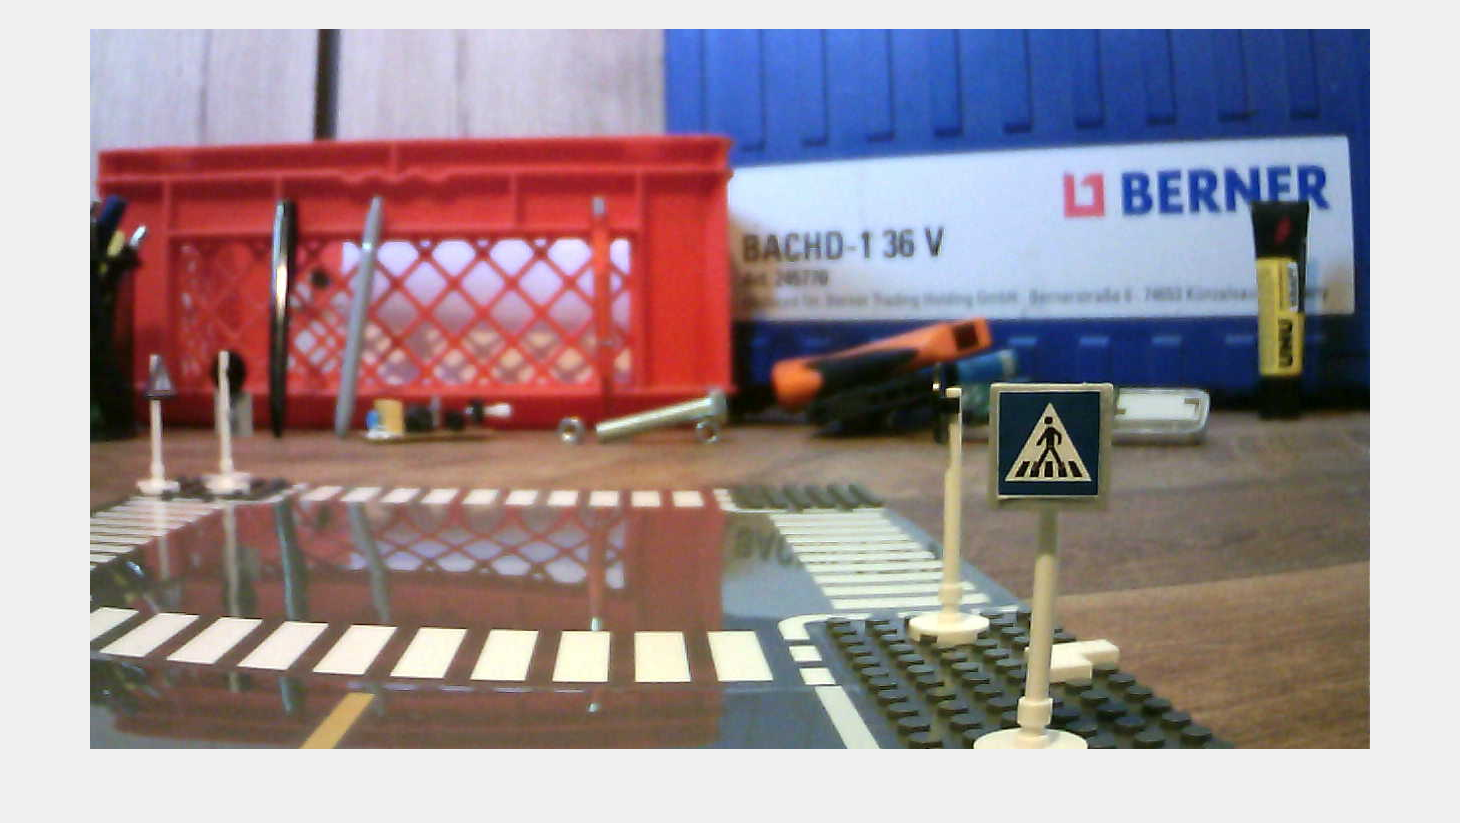

directory = "C:\Users\nicoh\OneDrive\Desktop\Matlabcode_Teamprojekt\Bilder\3 Rechteckige Schilder\Fussgaengerueberweg\Indoor_Kreuzung";
cd(directory);      % Arbeitsverzeichnis setzen

I = imread("Fussgaengerueberweg-2025-06-19__18.jpg");
imshow(I);

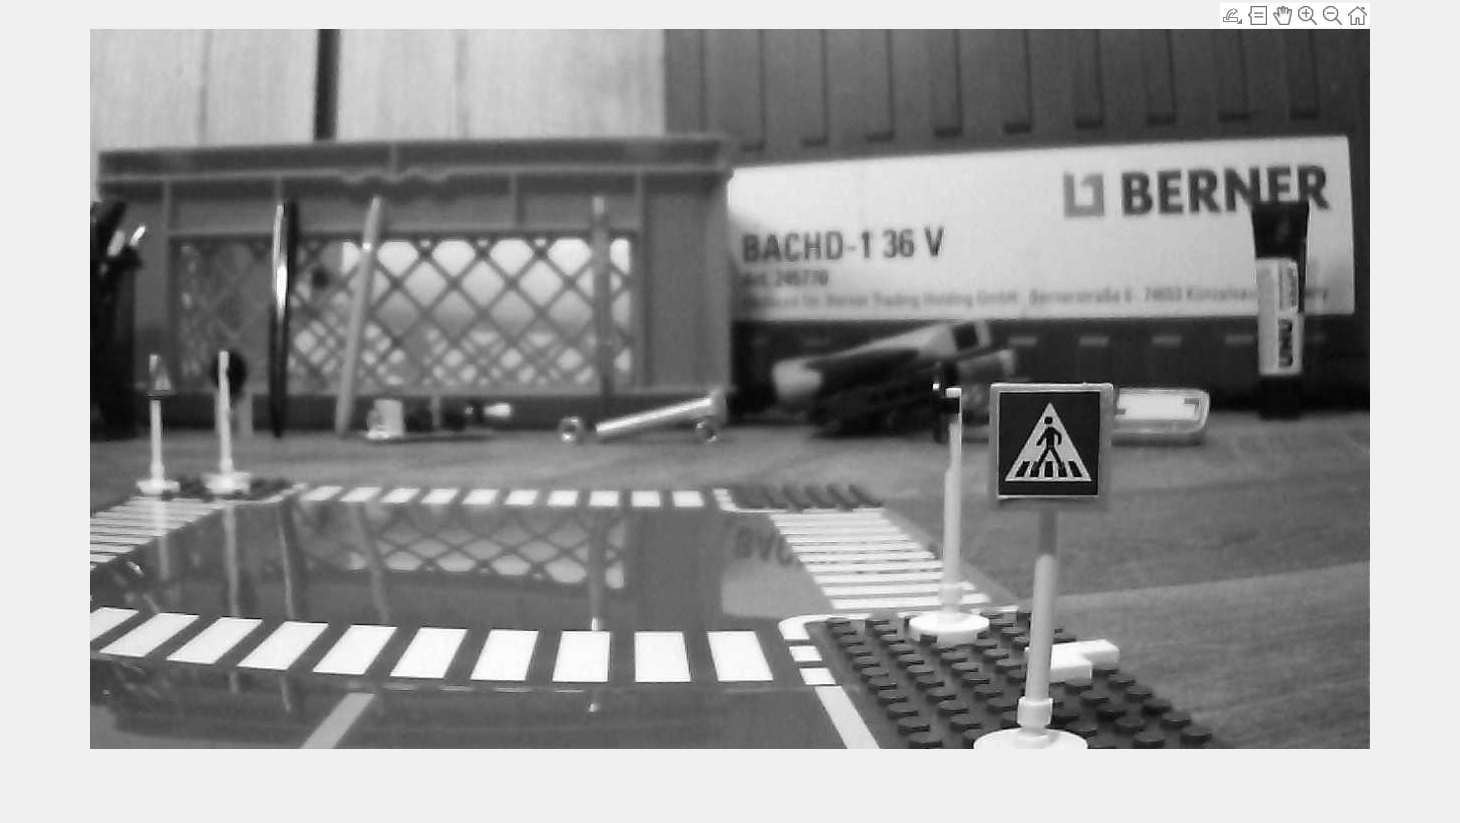

grayImage = rgb2gray(I);
imshow(grayImage);

[x, y, val] = impixel;

disp(['Grauwert an (', num2str(x), ',', num2str(y), '): ', num2str(val)]);

Error using horzcat
Dimensions of arrays being concatenated are not consistent.


% Schwellwert in Grauwerten (0–255)
% T = val(1);aus klick übernehmen
T=40;
BW = grayImage > T;
imshow(BW);
figure; 
% eintragen der Bilddatei in excel
% writematrix(string(Pfadschild), filename, 'WriteMode', 'append');
[centers, radii] = imfindcircles(BW, [20, 200], 'ObjectPolarity','bright','Sensitivity', 0.92 )
viscircles(centers, radii,'EdgeColor','r');